Requisitos: tener un interprete de python y chebfun en la pestaña de add-ons. 

Ejecutar pyversion("C:\Users\Luis\anaconda3\python.exe") con el folder de python, solo una vez al iniciar matlab.Descargar mpmath para python e importarlo en matlab

Parte de los zeros de la función zeta riemman

function zeros_t = zerost(n)
    mpmath = py.importlib.import_module('mpmath');
    mpmath.mp.dps = 15; % decimales de precisión
    zeros_t = arrayfun(@(k) mpmath.zetazero(int32(k)), 1:n, UniformOutput=0);
    zeros_t = cellfun(@(z) double(py.float(z.imag).real), zeros_t, UniformOutput=0)';
    zeros_t = cell2mat(zeros_t);
    zeros_t = 0.5+1i*zeros_t;
    zeros_t = [zeros_t; 1-zeros_t];
end

Función mobius

function m = mobius(n)
    if n == 1
        m = 1;
        return;
    end
    factors = factor(n);
    unique_factors = unique(factors);
    if numel(factors) ~= numel(unique_factors)
        m = 0;
        return;
    end
    m = (-1)^numel(unique_factors);
end

Función integral logarítmica

function li = li_function(y)
    % Aproximación de la función logarítmica integral
    % Usar la integración numérica para calcular li(y)
    if imag(y) == 0
        li = integral(@(t) 1 ./ log(t), 2, y, 'ArrayValued', true);
    else
        li = integral(@(t) 1 ./ log(t), 0, y, 'ArrayValued', true);
    end
end

Aproximación base

function R = R_function(X, N)
    % Parámetros:
    % X: Punto en el cual evaluar R(X)
    % N: Límite superior de la suma

    % Inicializar la suma
    R = 0;

    for n = 1:N
        % Calcular la función de Möbius para n
        mu_n = mobius(n);

        % Calcular li(X^(1/n))
        li_term = li_function(X^(1/n));

        % Sumar el término correspondiente
        R = R + (mu_n / n) * li_term;
    end
end

Creando la escalera de primos

val = 100; 
prueba = primes(val);
escalera = sort([prueba, prueba]);
contadores = sort([1:numel(prueba), 0:(numel(prueba)-1)]);

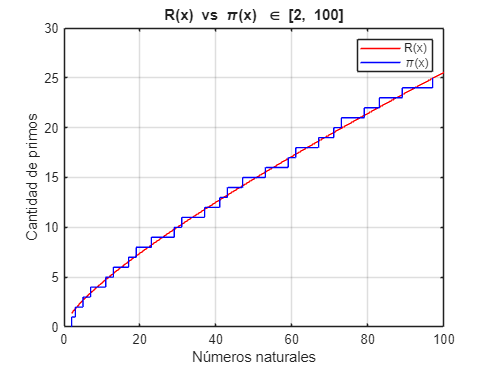

figure(1);
plot(2:val, arrayfun(@(x) R_function(x, 100), 2:val), 'r')
hold on;
plot(escalera, contadores, 'b')
xlabel('Números naturales');
ylabel('Cantidad de primos');
title('R(x) vs \pi(x) \in [2, 100]' );
grid on;
hold off;
legend('R(x)', '\pi(x)')

Cálculo de Rk, con k el número de ceros de la función zeta de riemman utilizados

function [xx, yy] = Rk(n, val)

    zeros_t = zerost(n);
    x  = chebfun('x',[2 val]);
    f1 = 1./log(x)- 1./((x.^2-1).*x.*log(x));
    f2 = @(z) exp(z)./z;
    intF1 = chebfun(sum(f1,2,x),[2 val]);
    
    mbk = nan(ceil(log(val)/log(2)-1),1); % cota a numeros primos
    for k = 1:size(mbk,1)
        mbk(k) = mobius(k)/k;
    end
    
    nz = 3*(val-3)+1;
    xx  = linspace(3,val,nz);
    yy = nan(nz,1);
    for j = 1:size(xx,2)
        xhat = xx(j);
        N=ceil(log(xhat)/log(2)-1);
        b = 0;
        for k = 1:N
            %for v (zeros_t)
            if(mbk(k)~=0)
                v = log(xhat)/k*imag(zeros_t);%
                SZ = real(sum(integral(@(s) f2(s+1i*v),-inf,log(xhat)/k/2,'ArrayValued',true)));
                J  = intF1(xhat^(1./k))-SZ+.4919628194400546;
                b  = b + J*mbk(k);
            end
            %end
        end
        yy(j) = b;
    end
end

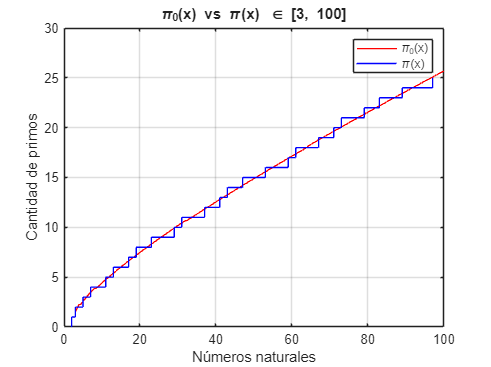

n = 0;
[xx, yy] = Rk(n, val);
figure(2)
plot(xx, yy, 'linewidth', 1, 'color', 'r');
hold on;
plot(escalera, contadores, 'b');
xlabel('Números naturales');
ylabel('Cantidad de primos');
title(strcat('\pi_{', num2str(n), '}(x)',' vs \pi(x) \in [3, 100]') );
legend(strcat('\pi_{', num2str(n), '}(x)'), '\pi(x)'); 
grid on;
hold off;